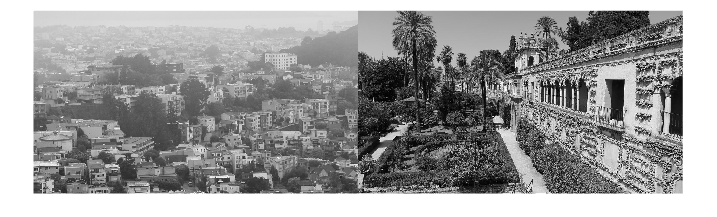

% High and low freq from last lecture
hf = im2double(rgb2gray(imread("sevilla.jpg")));

lf = imread("foggysf1.jpg");
lf = lf(500:1399, 1000:2599, :);
lf = im2double(rgb2gray(lf));
imshow([lf hf])

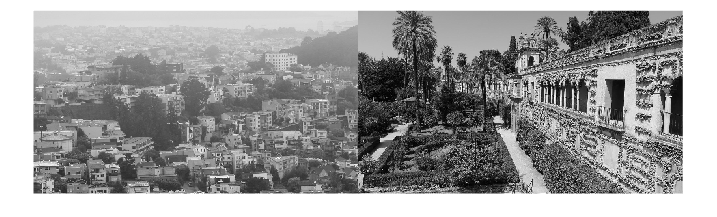


% Make image smaller by showing every other pixel
imshow([lf(1:2:end, 1:2:end) hf(1:2:end, 1:2:end)])

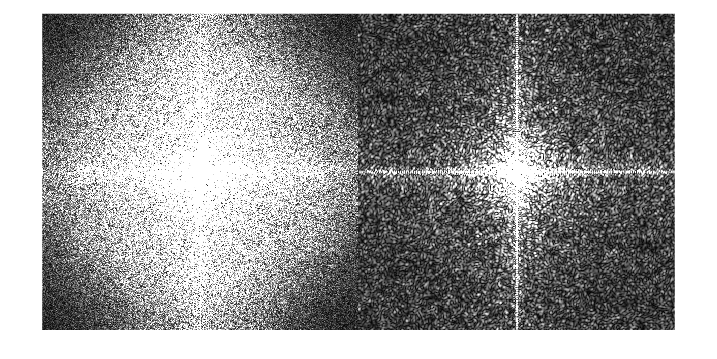

% Low frequency image is kinda unaffected, but high freuqency pattern has
% spots which is called aliasing. 

% Spatial domain is what we're familiar with, it is the color values of
% each pixel in an image represented in a matrix. 
% The frequency domain for a regular positive real valued spatial domain
% entries will be symmettric 

% Multiplication in spatial = convolution in frequency 

% We can translate spatial to frequency by taking samples (specific pixel
% values), where samples integrate up to one. For these samples that have
% distance t from each other, taking FT will give frequency curves repeated
% 1/t width from each other. 
% We can also multiply specific samples in spatial to get to a value,
% cooresponding to a convolution in frequency. 

% We can have constructive interference in this process where not having
% enough smaples will lead to a lot of repeated cones, some high frequency
% parts will add up with other cone bases, leading to
% higher than expected values. This is called aliasing. 
% We can fix this by taking more samples (t gets smaller, 1/t gets larger
% so more distance between cones). But this is not always ideal has it
% needs more data 

% Another anti-aliasing technique is applying a lowpass lfiter before
% sampling or repsampling points to get rid of it's high-frequency
% components and they don't collide. Let's implement this 
hf_samp = hf(1:4:622, 1:4:622);
hf = hf(1:622, 1:622);
imshow([abs(fftshift(fft2(hf))) abs(fftshift(fft2(hf_samp, 622, 622)))]/50)

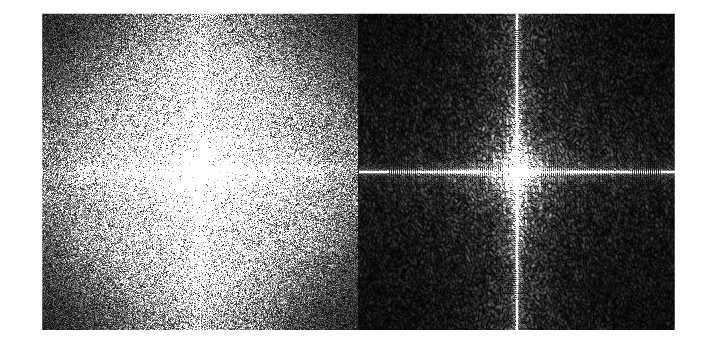

% We can make this nicer by taking the low frequency image and doing the
% same things, seeing it's more concentrated 
lf_samp = lf(1:4:622, 1:4:622);
lf = hf(1:622, 1:622);
imshow([abs(fftshift(fft2(lf))) abs(fftshift(fft2(lf_samp, 622, 622)))]/50)

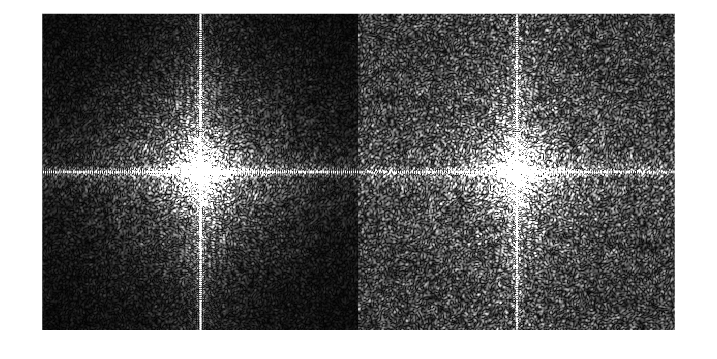


% Now let's apply the gaussian for an low pass anti-aliasing filter
hf_flit = imgaussfilt(hf, 1.5);
hf_flit_samp = hf_flit(1:4:end, 1:4:end);
imshow([abs(fftshift(fft2(hf_flit_samp, 622, 622))) abs(fftshift(fft2(hf_samp, 622, 622)))]/50)

% Less aliasing on right than left 